# Mechanisms of pain expectation learning

## Simple delta rule for learning the pain expectation: 

In this model, it is assumed that participants learn the future upcoming pain (pain expectation) through a feedback mechanism by which pain outcome rating (behavioral measure of subjective pain perception) acts as a reinforcer of the pain expectation rating (equation 1).  


$$\left(1\right)\;\;E_{\textrm{cue}} \left(t+1\right)=E_{\textrm{cue}} \left(t\right)+\alpha \times \delta \left(t\right)$$
 

In the above equation, E is the expectation of pain associated with a specific cue type (e.g., high-pain cue or low-pain cue) which is being updated by delta rule. 

Importantly, the reinforcer (or pain outcome rating) in the prediction error (t in equation 2) signal is dependent on the expectation itself (equation 3).


$$\left(2\right)\;\;$$

$$\delta \left(t\right)=\textrm{Pain}\left(t\right)-$$

$$E_{\textrm{cue}} \left(t\right)$$



$$\left(3\right)\;\;\textrm{Pain}\left(t\right)=\left(1-w\right)\times \textrm{Noxious}\left(t\right)+w\times E_{\textrm{cue}} \left(t\right)$$


It means that the proposed model assumes that the expectation of pain that is being learnt from pain outcome rating, is actually modulating the pain outcome rating in a way that the more expectation we have, the more pain outcome rating (reinforcer) we experience. In other words, pain which acts as a reinforcer in the model could be more painful if you are afraid of pain (equation 3). Therefore, there is a short circuit effect of expectation (that is driven by the cue) on the reinforcer that biases the prediction error (PE) by a positive feedback loop and is the core difference between the conventional RL models and our proposed model.

**Now let's do some coding:**

**loading data:**


%(this is the version that has at least 48 trials per person)

% only 5 subjects

**Initialization of parameters and optimization:**

% defining initial valus for the parameters:
% mdl1) (4 parameters) 'mdl1': (1) one alpha (2) one constant weight: w 
% (3) painerror (4) experror 
lb{1}=[0 0 0 0];
ub{1}=[1 1 100 100];


run_numbers=3;

load('table_pain_4mdls.mat');
subj_num_new=unique(table_pain.src_subject_id);


% for ii=1:length(subj_num_new)
for ii=1:3
ii
sub_no=subj_num_new(ii);
% 0) get the data matrix for the subject:
Data=table_pain(table_pain.src_subject_id==sub_no,:);
Data_lowpain=Data(strcmp(Data.param_stimulus_type, 'low_stim'),:);
Data_medpain=Data(strcmp(Data.param_stimulus_type, 'med_stim'),:);
Data_highpain=Data(strcmp(Data.param_stimulus_type, 'high_stim'),:);
% 1)	Calculate the Noxious inputs (1, 2, or 3) for each of the participants based on the average ratings of that participant on each of those real Noxious inputs. For example, to calculate the subjective Noxious 1 (48) for participant 1, we average the ratings on the trials that the participant has got 48-degree heat (and the pain rating is reported on 0-180 scale). 
% From pain rating vector: 
N(ii,1)=nanmean(Data_lowpain.event04_actual_angle);
N(ii,2)=nanmean(Data_medpain.event04_actual_angle);
N(ii,3)=nanmean(Data_highpain.event04_actual_angle);
% Noxious input vecotr for each participant:
Noxious{ii} = zeros(length(Data.param_stimulus_type),1);
Noxious{ii}(strcmp(Data.param_stimulus_type,'low_stim')) = N(ii,1);
Noxious{ii}(strcmp(Data.param_stimulus_type,'med_stim')) = N(ii,2);
Noxious{ii}(strcmp(Data.param_stimulus_type,'high_stim')) = N(ii,3);
% High_Cue vector for each participant:
High_Cue{ii} = strcmp(Data.param_cue_type,'high_cue');
% 2, 3, 4)	Calculate the Expectation and Pain matrices based on each model
% Calculate the nll based on the above equation
% For jj=1:20 % run 20 times to avoid being stuck in the 
%   Optimize the nll function and get the parameters and nll for each model and pick the best parameter
% End
% 5)	Calculate aic, bic, and nll or each model and compare different models together
Noxious_subj=Noxious{ii};
High_Cue_subj=High_Cue{ii};

        m=1;
        for model_type={'mdl1'}
            fit_fun=@(xpar)NLL(xpar, Data, model_type{1},Noxious_subj,High_Cue_subj);
            for jj=1:run_numbers
                initpar=lb{m}+rand(1,length(lb{m})).*(ub{m}-lb{m});
                [qpar{ii,m,jj}, nll(ii,m,jj), bic(ii,m,jj), nlike, aic(ii,m,jj)]=fit_fun_2(Data,fit_fun,initpar,lb{m},ub{m});
            end
            m=m+1;
        end
end

ii = 1

ii = 2

ii = 3

**Defining the NLL function (at the end of the code)**

## Two learning rates mechanism: 

Now, instead of only one learning rate, one can assume that the rate at which we learn can differ across different conditions. For example, one might learn the evidence that is congruent with their beliefs, at a higher rate than the evidence which is incongruent with their current beliefs (confirmation bias). In order to implement that, there should be two learning rates, one used for the congruent trials and the other one used for the incongruent trials. 


$$\left(4\right)\;\;\left\lbrace \begin{array}{ll}
\alpha_c  & \textrm{if}\;\delta \left(t\right)<0\;\&\;\textrm{low}\;\textrm{cue}\;\textrm{OR}\;\delta \left(t\right)>0\;\&\;\textrm{high}\;\textrm{cue}\\
\alpha_i  & \textrm{if}\;\delta \left(t\right)>0\;\&\;\textrm{low}\;\textrm{cue}\;\textrm{OR}\;\delta \left(t\right)<0\;\&\;\textrm{high}\;\textrm{cue}\;
\end{array}\right.$$


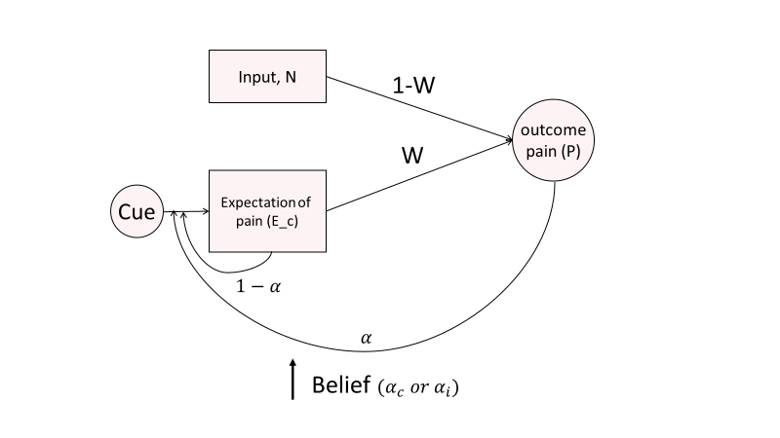

**Have a look at the learning rates for congrunet and incongruent trials:**

% dbdf



**Model comparison:**

% dbdf



**NLL function:**

function [negloglike]=NLL(xpar, Data, model_type,Noxious, High_Cue)
% % NLL %
%PURPOSE:  NLL calculation for parameter estimation, called by fit_fun().
%
%INPUT ARGUMENTS
%   xpar:       input parameters depending on the model type
%   Data:      Data for each subject
%   model_type:       'mdl1: one alpha, constant weight', 'mdl2: two alpha, constant weight',
% 'mdl3: one alpha, changing weight' ,'mdl4: two alpa, chanigng weight',
% 'mdl5: one alpha, changing weight (w on N)' ,'mdl6: two alpa, chanigng weight (w on N)'
%   Noxious: a vector of the Noxious inputs for different trials
%   High_Cue: a vector of cues (high (1) vs low(0)) for different trials


%OUTPUT ARGUMENTS
%   negloglike:      negaive log likelihood


%% defining the models:
num_trial=size(Data,1);  % number of trials
NLLs = zeros(1,num_trial);
NLLs_pain = zeros(1,num_trial);
NLLs_exp = zeros(1,num_trial);
negloglike=0;
rng('shuffle'); % random number generator shuffle
idx_ExpH = find(strcmp(Data.param_cue_type, 'high_cue'), 1);
idx_ExpL = find(strcmp(Data.param_cue_type, 'low_cue'), 1);
first_exp_high_cue = Data.event02_expect_angle(idx_ExpH);
first_exp_low_cue = Data.event02_expect_angle(idx_ExpL);


switch model_type
    case 'mdl1'
        % mdl1: one alpha, constant weight:
        % defining parameters:
        alpha=xpar(1);
        w=xpar(2);
        painerror=xpar(3);
        experror=xpar(4);
        % defingin expectations and pains:
        ExpectationH=first_exp_high_cue*ones(num_trial+1,1); % Expectation_highCue matrix
        ExpectationL=first_exp_low_cue*ones(num_trial+1,1); % Expectation_lowCue matrix
        Pain=zeros(num_trial+1,1); % Pain matrix
        PE=zeros(num_trial+1,1); % Pain predcition error matrix
        PainH=zeros(num_trial+1,1); % Pain matrix for high cues
        PainL=zeros(num_trial+1,1); % Pain matrix for low cues
        for ii=1:num_trial
            if High_Cue(ii)==1
                Pain(ii,1)=(1-w)*Noxious(ii,1)+w*ExpectationH(ii,1);
                PE(ii,1)=Pain(ii,1)-ExpectationH(ii,1);
                ExpectationH(ii+1,1)=ExpectationH(ii,1)+alpha*PE(ii,1);
                ExpectationL(ii+1,1)=ExpectationL(ii,1);
                PainH(ii,1)=Pain(ii,1);
                PainL(ii,1)=nan;
                NLLs_pain(ii) = -log(max(realmin,normpdf(Data.event04_actual_angle(ii),Pain(ii,1),painerror))); % pain log likelihood
                NLLs_exp(ii) = -log(max(realmin,normpdf(Data.event02_expect_angle(ii),ExpectationH(ii,1),experror))); % exp log likelihood
                NLLs(ii)=NLLs_pain(ii)+NLLs_exp(ii);
            else
                Pain(ii,1)=(1-w)*Noxious(ii,1)+w*ExpectationL(ii,1);
                PE(ii,1)=Pain(ii,1)-ExpectationL(ii,1);
                ExpectationL(ii+1,1)=ExpectationL(ii,1)+alpha*PE(ii,1);
                ExpectationH(ii+1,1)=ExpectationH(ii,1);
                PainL(ii,1)=Pain(ii,1);
                PainH(ii,1)=nan;
                NLLs_pain(ii) = -log(max(realmin,normpdf(Data.event04_actual_angle(ii),Pain(ii,1),painerror))); % pain log likelihood
                NLLs_exp(ii) = -log(max(realmin,normpdf(Data.event02_expect_angle(ii),ExpectationL(ii,1),experror))); % exp log likelihood
                NLLs(ii)=NLLs_pain(ii)+NLLs_exp(ii);
            end
            % calculating NLL (based on NLL_exp and NLL_pain)
            negloglike=negloglike+NLLs(ii);  % calculate log likelihood
        end


    case 'mdl2'
        % 'mdl2: two alpha, constant weight':
        % defining parameters:
        alpha_c=xpar(1);
        alpha_i=xpar(2);
        w=xpar(3);
        painerror=xpar(4);
        experror=xpar(5);
        % defingin expectations and pains:
        ExpectationH=first_exp_high_cue*ones(num_trial+1,1); % Expectation_highCue matrix
        ExpectationL=first_exp_low_cue*ones(num_trial+1,1); % Expectation_lowCue matrix
        Pain=zeros(num_trial+1,1); % Pain matrix
        PE=zeros(num_trial+1,1); % Pain predcition error matrix
        PainH=zeros(num_trial+1,1); % Pain matrix for high cues
        PainL=zeros(num_trial+1,1); % Pain matrix for low cues
        for ii=1:num_trial
            if High_Cue(ii)==1
                Pain(ii,1)=(1-w)*Noxious(ii,1)+w*ExpectationH(ii,1);
                PE(ii,1)=Pain(ii,1)-ExpectationH(ii,1);
                if PE(ii,1)>=0
                    alpha=alpha_c;
                else
                    alpha=alpha_i;
                end
                ExpectationH(ii+1,1)=ExpectationH(ii,1)+alpha*PE(ii,1);
                ExpectationL(ii+1,1)=ExpectationL(ii,1);
                PainH(ii,1)=Pain(ii,1);
                PainL(ii,1)=nan;
                NLLs_pain(ii) = -log(max(realmin,normpdf(Data.event04_actual_angle(ii),Pain(ii,1),painerror))); % pain log likelihood
                NLLs_exp(ii) = -log(max(realmin,normpdf(Data.event02_expect_angle(ii),ExpectationH(ii,1),experror))); % exp log likelihood
                NLLs(ii)=NLLs_pain(ii)+NLLs_exp(ii);
            else
                Pain(ii,1)=(1-w)*Noxious(ii,1)+w*ExpectationL(ii,1);
                PE(ii,1)=Pain(ii,1)-ExpectationL(ii,1);
                if PE(ii,1)>=0
                    alpha=alpha_i;
                else
                    alpha=alpha_c;
                end
                ExpectationL(ii+1,1)=ExpectationL(ii,1)+alpha*PE(ii,1);
                ExpectationH(ii+1,1)=ExpectationH(ii,1);
                PainL(ii,1)=Pain(ii,1);
                PainH(ii,1)=nan;
                NLLs_pain(ii) = -log(max(realmin,normpdf(Data.event04_actual_angle(ii),Pain(ii,1),painerror))); % pain log likelihood
                NLLs_exp(ii) = -log(max(realmin,normpdf(Data.event02_expect_angle(ii),ExpectationL(ii,1),experror))); % exp log likelihood
                NLLs(ii)=NLLs_pain(ii)+NLLs_exp(ii);
            end
            % calculating sum of squared errors (based on the sum of errors for Pain and expectation)
            negloglike=negloglike+NLLs(ii);  % calculate log likelihood
        end

    otherwise
        error('Unexpected model type')
end
end




function [qpar, negloglike, bic, nlike, aic]=fit_fun_2(Data,fit_fun,initpar,lb,ub)    
% % fit_fun %
%PURPOSE:   Fit the choice behavior to a model using maximum likelihood estimate
%AUTHORS:   AC Kwan 170518, Ethan Trepka 210220, Aryan Yazdanpanah 

%
%INPUT ARGUMENTS
%   stats:      stats of the game
%   fit_fun:    the model to fit
%   initpar:    initial values for the parameters
%   lb:         lower bound values for the parameters (if used)
%   ub:         upper bound values for the parameters (if used)
%
%OUTPUT ARGUMENTS
%   qpar:       extracted parameters
%   negloglike: negative log likelihood
%   bic:        Bayesian information criterion
%   nlike:      normalized likelihood

%%
maxit=1e7;
maxeval=1e7;
op=optimset('fminsearch');
op.MaxIter=maxit;
op.MaxFunEvals=maxeval;

% func_handle = str2func(fit_fun);
% if ~exist('lb','var')
%     [qpar, negloglike, exitflag]=fminsearch(func_handle, initpar, op, [stats.c stats.r]);
% else
%     [qpar, negloglike, exitflag]=fmincon(func_handle, initpar, [], [], [], [], lb, ub, [], op, [stats.c stats.r]);
[qpar, negloglike, exitflag]=fmincon(fit_fun, initpar, [], [], [], [], lb, ub, [], op);
% end
if exitflag==0
    qpar=nan(size(qpar));   %did not converge to a solution, so return NaN
    negloglike=nan;
end

%% BIC, bayesian information criterion
%BIC = -2*logL + klogN
%L = negative log-likelihood, k = number of parameters, N = number of trials
%larger BIC value is worse because more parameters is worse, obviously
bic = 2*negloglike + numel(initpar)*log(size(Data,1));

%% AIC, Aikake information crieterion
%AIC = -2*logL + 2k
%L = negative log-likelihood, k = number of parameters
aic = 2*negloglike + numel(initpar)*2;

%% Normalized likelihood 
%(Ito and Doya, PLoS Comp Biol, 2015)
nlike = exp(-1*negloglike)^(1/(size(Data,1)));

end
